close all; 

g = 9.8; % m/s^2
m = 0.068; % kg
dist_xy = 0.047625; 
dist_r = sqrt(2*dist_xy^2); % in meters
diam = 0.066;
J_xx = 0.69*10^-4; % kg*m^2
J_yy = 0.775*10^-4; % kg*m^2
J_zz = 1.5*10^-4; % kg*m^2
r_prop = diam/2; % in meters
m_prop = 0.009/4; % in kg
I_body = m_prop*r_prop^2;
J_p = I_body + m_prop*dist_r^2;
rho = 1.293; % kg/m^3

pt1 = [10400/60; 0.078]; 
pt2 = [29600/60; 0.092];
slope = (pt2(2)-pt1(2))/(pt2(1)-pt1(1));
intercept = pt2(2)-slope*pt2(1);
C_t = @(n) slope*n + intercept;
C_p = 0.041;


syms p_x p_x_dot p_y p_y_dot p_z p_z_dot phi phi_dot theta theta_dot psi psi_dot throttle aileron elevator rudder

R_phi = [1 0 0;
         0 cos(phi) sin(phi);
         0 -sin(phi) cos(phi)];
R_theta = [cos(theta) 0 -sin(theta);
           0 1 0;
           sin(theta) 0 cos(theta)];
R_psi = [cos(psi) sin(psi) 0;
         -sin(psi) cos(psi) 0;
         0 0 1];
R = R_phi*R_theta*R_psi;
H = [1 0 -sin(theta);
     0 cos(phi) sin(phi)*cos(theta);
     0 -sin(phi) cos(phi)*cos(theta)];

syms theta_eq F_t
K_c = 0.22;
myfun = @(x) -sin(x)/(cos(x)^2)-K_c; 
theta_hover = fzero(myfun,0.1)

theta_hover = -0.2119

mass = 0.068;
gravity = 9.8;
F_hover = mass*gravity*cos(theta_hover)

F_hover = 0.6515

V_b_0 = double(subs(R*[1; 0; 0],[phi theta psi],[0 theta_hover 0]))

V_b_0 =     0.9776
         0
   -0.2103



p_N_0 = 0;
p_E_0 = 0;
p_D_0 = 0;

u_0 = V_b_0(1);
v_0 = V_b_0(2);
w_0 = V_b_0(3);

phi_0 = 0;
theta_0 = theta_hover;
psi_0 = 0;

p_0 = 0;
q_0 = 0;
r_0 = 0;

T_0 = F_hover;
A_0 = 0;
E_0 = 0;
R_0 = 0;

K_drag = [K_c 0 0;
    0 K_c 0;
    0 0 0];

J = [J_xx 0 0; 0 J_yy 0; 0 0 J_zz];
W_0 = [T_0; A_0; E_0; R_0];
x_0 = [p_N_0; p_E_0; p_D_0; w_0; v_0; phi_0; p_0; u_0; theta_0; q_0; psi_0; r_0];

n_eq = fzero(@(n)4*(C_t(n)*rho*diam^4*n^2)-F_hover,200);
a = C_t(n_eq)*rho*diam^4;
b = C_t(n_eq)*rho*diam^4*dist_xy;
c = b

c = 9.6753e-08

d = C_p*rho*diam^5/(2*pi);

M = [1/a 1/b 1/c -1/d;
      1/a -1/b 1/c 1/d;
      1/a -1/b -1/c -1/d;
      1/a 1/b -1/c 1/d];
nu = 1/4*M*W_0;
n = sqrt(nu)

n =   283.1482
  283.1482
  283.1482
  283.1482


% n1 = n(1);
% n2 = n(2);
% n3 = n(3);
% n4 = n(4);
n_eq = abs(n(1));

syms p_N p_E p_D w v p u q r n1 n2 n3 n4
V_b = [u;v;w];
p_E_dot = R^-1*V_b;
omega_bE = [p;q;r];
Theta_dot = H^-1*omega_bE;
F_t_b = [0; 0; -throttle];
% F_t_b = [0; 0; -a*(n1^2+n2^2+n3^2+n4^2)];
F_a_b = F_t_b'*K_drag*V_b;
F_g_b = R*[0; 0; m*g];
M_t_b = [aileron; elevator; rudder];
% M_t_b = [b*(n1^2-n2^2-n3^3+n4^2); c*(n1^2+n2^2-n3^2-n4^2); d*(-n1^2+n2^2-n3^2+n4^2)];
H_p_b = [0; 0; J_p*2*pi*(n1-n2+n3-n4)]

$$H\_p\_b = \left(\begin{array}{c} 0\\ 0\\ \frac{2933974571915261\,n_{1}}{36893488147419103232}-\frac{2933974571915261\,n_{2}}{36893488147419103232}+\frac{2933974571915261\,n_{3}}{36893488147419103232}-\frac{2933974571915261\,n_{4}}{36893488147419103232} \end{array}\right)$$

M_omega_b = cross(omega_bE,H_p_b)

$$M\_omega\_b = \left(\begin{array}{c} q\,\left(\frac{2933974571915261\,n_{1}}{36893488147419103232}-\frac{2933974571915261\,n_{2}}{36893488147419103232}+\frac{2933974571915261\,n_{3}}{36893488147419103232}-\frac{2933974571915261\,n_{4}}{36893488147419103232}\right)\\ -p\,\left(\frac{2933974571915261\,n_{1}}{36893488147419103232}-\frac{2933974571915261\,n_{2}}{36893488147419103232}+\frac{2933974571915261\,n_{3}}{36893488147419103232}-\frac{2933974571915261\,n_{4}}{36893488147419103232}\right)\\ 0 \end{array}\right)$$

V_b_dot = (1/m)*(F_t_b + F_a_b + F_g_b - cross(omega_bE,m.*V_b));
omega_bE_dot = J^-1*(M_t_b + M_omega_b - cross(omega_bE,J*V_b));
f = [p_E_dot(1); p_E_dot(2); p_E_dot(3); V_b_dot(3); V_b_dot(2); Theta_dot(1); omega_bE_dot(1); V_b_dot(1); Theta_dot(2); omega_bE_dot(2); Theta_dot(3); omega_bE_dot(3)];
x = [p_N; p_E; p_D; w; v; phi; p; u; theta; q; psi; r];
W = [throttle; aileron; elevator; rudder];



f_x = jacobian(f,x);
f_u = jacobian(f,W);

A_1 = subs(f_x,x,x_0);
A_2 = subs(A_1);
A_3 = subs(A_2,[n1 n2 n3 n4],[n_eq n_eq n_eq n_eq]);
A_4 = subs(A_3,W,W_0);
A = double(subs(A_4,rho,1.293))

A =          0         0         0   -0.2103         0         0         0    0.9776    0.0000         0         0         0
         0         0         0         0    1.0000    0.2103         0         0         0         0    1.0000         0
         0         0         0    0.9776         0         0         0    0.2103   -1.0000         0         0         0
         0         0         0         0         0         0         0         0    2.0607    0.9776         0         0
         0         0         0         0         0    9.5809   -0.2103         0         0         0         0   -0.9776
         0         0         0         0         0         0    1.0000         0         0         0         0   -0.2151
         0         0         0         0         0         0         0         0         0    0.4571         0         0
         0         0         0         0         0         0         0         0   -9.5809    0.2103         0         0
         0         0        


B_1 = subs(f_u,x,x_0);
B_2 = subs(B_1);
B_3 = subs(B_2,[n1 n2 n3 n4],[n_eq n_eq n_eq n_eq]);
B = double(subs(B_3,W,W_0))

B = 	1.0e+04 *

         0         0         0         0
         0         0         0         0
         0         0         0         0
   -0.0015         0         0         0
         0         0         0         0
         0         0         0         0
         0    1.4493         0         0
         0         0         0         0
         0         0         0         0
         0         0    1.2903         0


D = 0;

A_throttle = A(3:4,3:4)

A_throttle =          0    0.9776
         0         0


B_throttle = B(3:4,1)

B_throttle =          0
  -14.7059


C_throttle = eye(2);
sys_throttle = ss(A_throttle,B_throttle,C_throttle,D);
H_throttle = tf(sys_throttle)

H_throttle =
 
  From input to output...
       -14.38
   1:  ------
        s^2
 
       -14.71
   2:  ------
         s
 
Continuous-time transfer function.



Co_throttle = ctrb(A_throttle,B_throttle);
Ob_throttle = obsv(A_throttle,C_throttle);
unco_throttle = length(A_throttle) - rank(Co_throttle)

unco_throttle = 0

unob_throttle = length(A_throttle) - rank(Ob_throttle)

unob_throttle = 0


A_aileron = A(5:7,5:7);
B_aileron = B(5:7,2);
C_aileron = eye(3);

sys_aileron = ss(A_aileron,B_aileron,C_aileron,D);
H_aileron = tf(sys_aileron)

H_aileron =
 
  From input to output...
       -3047 s + 1.389e05
   1:  ------------------
              s^3
 
       1.449e04
   2:  --------
         s^2
 
       1.449e04
   3:  --------
          s
 
Continuous-time transfer function.



Co_aileron = ctrb(A_aileron,B_aileron);
Ob_aileron = obsv(A_aileron,C_aileron);
unco_aileron = length(A_aileron) - rank(Co_aileron)

unco_aileron = 0

unob_aileron = length(A_aileron) - rank(Ob_aileron)

unob_aileron = 0


A_elevator = A(8:10,8:10);
B_elevator = B(8:10,3);
C_elevator = eye(3);

sys_elevator = ss(A_elevator,B_elevator,C_elevator,D);
H_elevator = tf(sys_elevator)

H_elevator =
 
  From input to output...
       2713 s - 1.236e05
   1:  -----------------
              s^3
 
       1.29e04
   2:  -------
         s^2
 
       1.29e04
   3:  -------
          s
 
Continuous-time transfer function.



Co_elevator = ctrb(A_elevator,B_elevator);
Ob_elevator = obsv(A_elevator,C_elevator);
unco_elevator = length(A_elevator) - rank(Co_elevator)

unco_elevator = 0

unob_elevator = length(A_elevator) - rank(Ob_elevator)

unob_elevator = 0


A_rudder = A(11:12,11:12);
B_rudder = B(11:12,4);
C_rudder = eye(2);

sys_rudder = ss(A_rudder,B_rudder,C_rudder,D);
H_rudder = tf(sys_rudder)

H_rudder =
 
  From input to output...
       6819
   1:  ----
       s^2
 
       6667
   2:  ----
        s
 
Continuous-time transfer function.



Co_rudder = ctrb(A_rudder,B_rudder);
Ob_rudder = obsv(A_rudder,C_rudder);
unco_rudder = length(A_rudder) - rank(Co_rudder)

unco_rudder = 0

unob_rudder = length(A_rudder) - rank(Ob_rudder)

unob_rudder = 0


A_guid = A(1:2,1:2);
B_guid = [A(1,8) A(1,11);
          A(2,8) A(2,11)];
C_guid = eye(2);

sys_guid = ss(A_guid,B_guid,C_guid,D);
H_guid = tf(sys_guid)

H_guid =
 
  From input 1 to output...
       0.9776
   1:  ------
         s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       1
   2:  -
       s
 
Continuous-time transfer function.



Co_guid = ctrb(A_guid,B_guid);
Ob_guid = obsv(A_guid,C_guid);
unco_guid = length(A_guid) - rank(Co_guid)

unco_guid = 0

unob_guid = length(A_guid) - rank(Ob_guid)

unob_guid = 0

Wrench_0 = [0; 0; 0; 0];
Wrench_step = [0; 0.001; 0; 0.001];

t = linspace(0,10,10000);
u_throttle = zeros(length(t),1);    
u_aileron = zeros(length(t),1);
u_elevator = zeros(length(t),1);
u_rudder = zeros(length(t),1);

u_throttle(t <= 3) = Wrench_0(1);
u_throttle(t > 3) = Wrench_step(1);
u_aileron(t > 3) = Wrench_step(2);
u_elevator(t > 3) = Wrench_step(3);
u_rudder(t > 3) = Wrench_step(4);

D = [];


syms phi theta psi phi_dot theta_dot psi_dot
R_phi = [1 0 0;
         0 cos(phi) sin(phi);
         0 -sin(phi) cos(phi)];
R_theta = [cos(theta) 0 -sin(theta);
           0 1 0;
           sin(theta) 0 cos(theta)];
R_psi = [cos(psi) sin(psi) 0;
         -sin(psi) cos(psi) 0;
         0 0 1];
R_phi*[phi_dot;0;0] + R_phi*R_theta*[0;theta_dot;0] + R_phi*R_theta*R_psi*[0;0;psi_dot]

$$ans = \left(\begin{array}{c} \dot{\varphi }-\dot{\psi }\,\sin\left(\theta \right)\\ \dot{\theta }\,\cos\left(\varphi \right)+\dot{\psi }\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \dot{\psi }\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\dot{\theta }\,\sin\left(\varphi \right) \end{array}\right)$$

H = [1 0 -sin(theta);
     0 cos(phi) sin(phi)*cos(theta);
     0 -sin(phi) cos(phi)*cos(theta)];
H_inv = inv(H)  

$$H\_inv = \begin{array}{l} \left(\begin{array}{ccc} 1 & \frac{\sin\left(\varphi \right)\,\sin\left(\theta \right)}{\sigma_{1}} & \frac{\cos\left(\varphi \right)\,\sin\left(\theta \right)}{\sigma_{1}}\\ 0 & \frac{\cos\left(\varphi \right)}{{\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2}} & -\frac{\sin\left(\varphi \right)}{{\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2}}\\ 0 & \frac{\sin\left(\varphi \right)}{\sigma_{1}} & \frac{\cos\left(\varphi \right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,{\cos\left(\varphi \right)}^{2}+\cos\left(\theta \right)\,{\sin\left(\varphi \right)}^{2} \end{array}$$


R_phi*R_theta

$$ans = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right)\\ \sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \cos\left(\varphi \right)\,\sin\left(\theta \right) & -\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

R = R_phi*R_theta*R_psi

$$R = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & -\sin\left(\theta \right)\\ \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

R_inv = inv(R)


J_p = 1.2657*10^(-5);

J_xx = 0.69*10^(-4);
J_yy = 0.775*10^(-4);
J_zz = 1.5*10^(-4);
J = [J_xx 0 0;
     0 J_yy 0;
     0 0 J_zz];
J_inv = inv(J)

J_inv = 	1.0e+04 *

    1.4493         0         0
         0    1.2903         0
         0         0    0.6667


        
K_c = 0.22;
m = 0.068; %kg
g = 9.8;

syms theta_eq F_t
myfun = @(x) -sin(x)/(cos(x)^2)-K_c; 
theta_hover = fzero(myfun,0.1)

theta_hover = -0.2119

F_hover = m*g*cos(theta_hover)

F_hover = 0.6515

V_b_0 = [0;0;0];  
% V_b_0 = double(subs(R*[1; 0; 0],[phi theta psi],[0 theta_hover 0]))
M_b_0 = [0; 0; 0];  
Theta_0 = [0;0;0];
% Theta_0 = [0; theta_hover; 0];
omega_0 = [0;0;0];
p_ned_0 = [0;0;0];

pt1 = [10400/60; 0.078]; 
pt2 = [29600/60; 0.092];
slope = (pt2(2)-pt1(2))/(pt2(1)-pt1(1));
intercept = pt2(2)-slope*pt2(1);
C_t = @(n) slope*n + intercept;
C_p = 0.041;
dist_xy = 0.047625; 
rho = 1.293; 
diam = 0.066;

n_eq = fzero(@(n)4*(C_t(n)*rho*diam^4*n^2)-m*g,200);
a = C_t(n_eq)*rho*diam^4;
b = C_t(n_eq)*rho*diam^4*dist_xy;
c = b

c = 9.6906e-08

d = C_p*rho*diam^5/(2*pi);
coeffs = [a;b;c;d]

coeffs = 	1.0e+-5 *

    0.2035
    0.0097
    0.0097
    0.0011


% M = [1/a 1/b 1/c -1/d;
%       1/a -1/b 1/c 1/d;
%       1/a -1/b -1/c -1/d;
%       1/a 1/b -1/c 1/d];
M = [a a a a;
    b -b -b b;
    c c -c -c;
    -d d -d d];
M_inv = inv(M)  

M_inv = 	1.0e+07 *

    0.0123    0.2580    0.2580   -2.3660
    0.0123   -0.2580    0.2580    2.3660
    0.0123   -0.2580   -0.2580   -2.3660
    0.0123    0.2580   -0.2580    2.3660



% Wrench_0 = [0; 0; 0; 0]
% Wrench_step = [0; 0; 0; 0]

V_b_command = double(subs(R*[1; 0; 0],[phi theta psi],[0 theta_hover 0]))

V_b_command =     0.9776
         0
   -0.2103



K_T = place(A_throttle, B_throttle, [-3,-2])

K_T =    -0.4173   -0.3400


K_A = place(A_aileron, B_aileron, [-4,-2,-1]);
K_E = place(A_elevator, B_elevator, [-4,-2,-1]);
K_R = place(A_rudder, B_rudder, [-3,-2]);

cmd_0 = [0;0;0;0];
cmd_hover = [-1;0;0;0];
cmd_forward = [0;0;V_b_command(1);0]

cmd_forward =          0
         0
    0.9776
         0


Finding the Closed loop Transfer function

Throttle

s = tf('s');
C_regulated_throttle = [1 0];
H_c_throttle= C_regulated_throttle*(s*eye(2)-A_throttle+B_throttle*K_T)^-1*B_throttle

H_c_throttle =
 
     -14.38
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.




%% Invert it
gain_throttle = dcgain(H_c_throttle)

gain_throttle = -2.3962


%% Take the DC gain
F_throttle = gain_throttle^-1

F_throttle = -0.4173

Aileron

C_regulated_aileron = [1 0 0];
H_c_aileron= C_regulated_aileron*(s*eye(3)-A_aileron+B_aileron*K_A)^-1*B_aileron

H_c_aileron =
 
    -3047 s + 1.389e05
  ----------------------
  s^3 + 7 s^2 + 14 s + 8
 
Continuous-time transfer function.




%% Invert it
gain_aileron = dcgain(H_c_aileron)

gain_aileron = 1.7357e+04


%% Take the DC gain
F_aileron = gain_aileron^-1

F_aileron = 5.7615e-05

Elevator

C_regulated_elevator = [1 0 0];
H_c_elevator = C_regulated_elevator*(s*eye(3)-A_elevator+B_elevator*K_E)^-1*B_elevator

H_c_elevator =
 
    2713 s - 1.236e05
  ----------------------
  s^3 + 7 s^2 + 14 s + 8
 
Continuous-time transfer function.




%% Invert it
gain_elevator = dcgain(H_c_elevator)

gain_elevator = -1.5453e+04


%% Take the DC gain
F_elevator = gain_elevator^-1

F_elevator = -6.4712e-05

Rudder

C_regulated_rudder = [1 0];
H_c_rudder= C_regulated_rudder*(s*eye(2)-A_rudder+B_rudder*K_R)^-1*B_rudder

H_c_rudder =
 
      6819
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.




%% Invert it
gain_rudder = dcgain(H_c_rudder)

gain_rudder = 1.1365e+03


%% Take the DC gain
F_rudder = gain_rudder^-1

F_rudder = 8.7988e-04


m = 0.068;
g = 9.8;

% a = 2.031550751419260e-06;
% b = 9.675260453634224e-08;
% c = 9.675260453634224e-08;
% d = 1.056628184682481e-08;
% M = [1/a 1/b 1/c -1/d;
%       1/a -1/b 1/c 1/d;
%       1/a -1/b -1/c -1/d;
%       1/a 1/b -1/c 1/d];
% W = [m*g; 0.004; 0.004; 0.004];

mydata = load('RSdata_Kalman.mat')

mydata = struct with fields:
                 rt_tout: [1600×1 double]
           rt_ScopeData4: [1×1 struct]
         rt_motor_speeds: [1×1 struct]
                    rt_u: [1×1 struct]
                    rt_v: [1×1 struct]
                    rt_w: [1×1 struct]
        rt_xhat_elevator: [1×1 struct]
         rt_xhat_aileron: [1×1 struct]
        rt_xhat_throttle: [1×1 struct]
                    rt_p: [1×1 struct]
                    rt_q: [1×1 struct]
                  rt_a_z: [1×1 struct]
                  rt_a_y: [1×1 struct]
                  rt_a_x: [1×1 struct]
         rt_z_ultrasonic: [1×1 struct]
             rt_pressure: [1×1 struct]
                    rt_r: [1×1 struct]
                       A: [12×12 double]
                     A_0: 0
                     A_1: [12×12 sym]
                     A_2: [12×12 sym]
                     A_3: [12×12 sym]
                     A_4: [12×12 sym]
                 A_a_dis: [2×2 double]
               A_aileron: [3×3 double]
      


%ms = mydata.rt_motor_speeds.signals.values;

% u = mydata.rt_optical_flow.signals.values(:,1);
% v = mydata.rt_optical_flow.signals.values(:,2);
% w = mydata.rt_optical_flow.signals.values(:,3);
u = mydata.rt_u.signals.values;
v = mydata.rt_v.signals.values;
w = mydata.rt_w.signals.values;
a_x = mydata.rt_a_x.signals.values;
a_y = mydata.rt_a_y.signals.values;
a_z = mydata.rt_a_z.signals.values;
p = mydata.rt_p.signals.values;
q = mydata.rt_q.signals.values;
r = mydata.rt_r.signals.values;
p_0 = mydata.rt_pressure.signals.values;
z_us = mydata.rt_z_ultrasonic.signals.values;

all_data = [u, v, w, a_x, a_y, a_z, p, q, r, p_0, z_us];
noise = zeros(size(all_data,1),size(all_data,2));
labels = ["u", "v", "w", "a_x", "a_y", "a_z", "p", "q", "r", "p_0","z_us"];

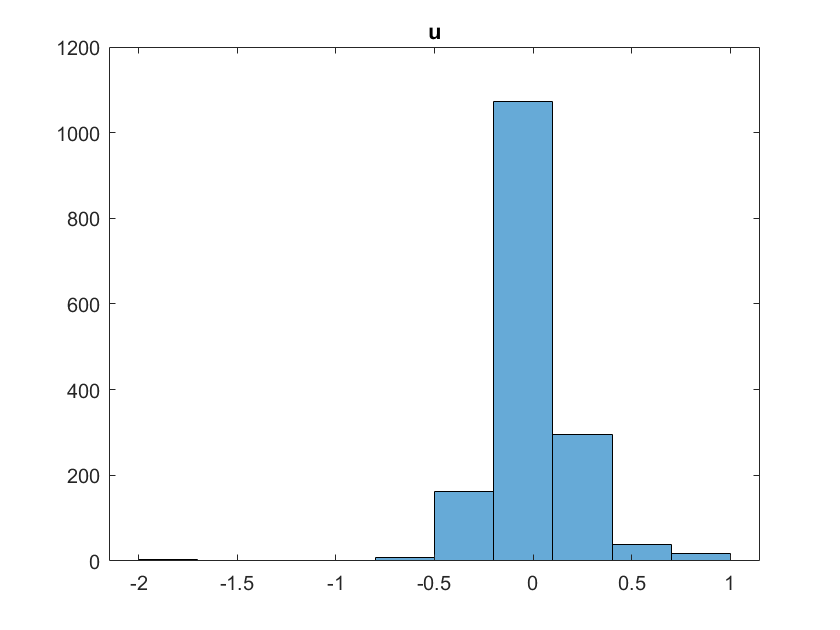

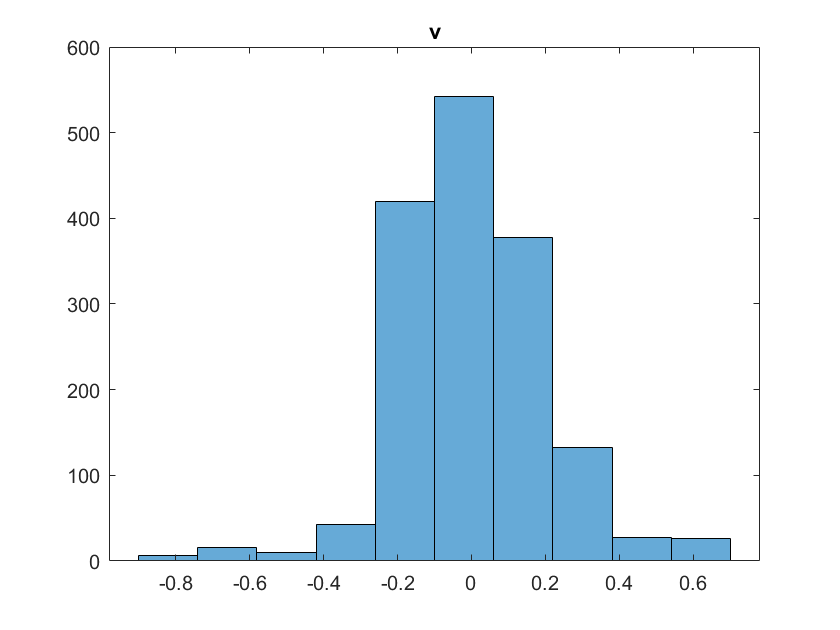

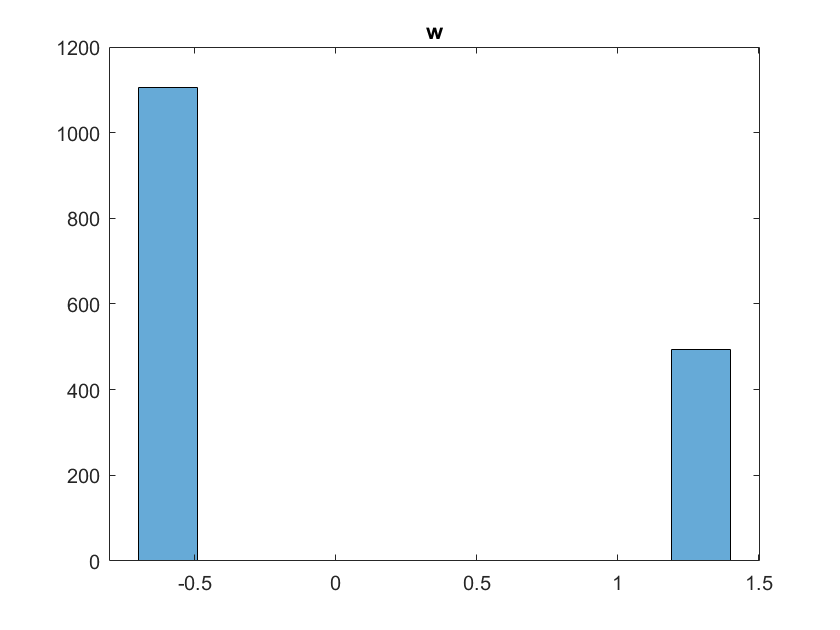

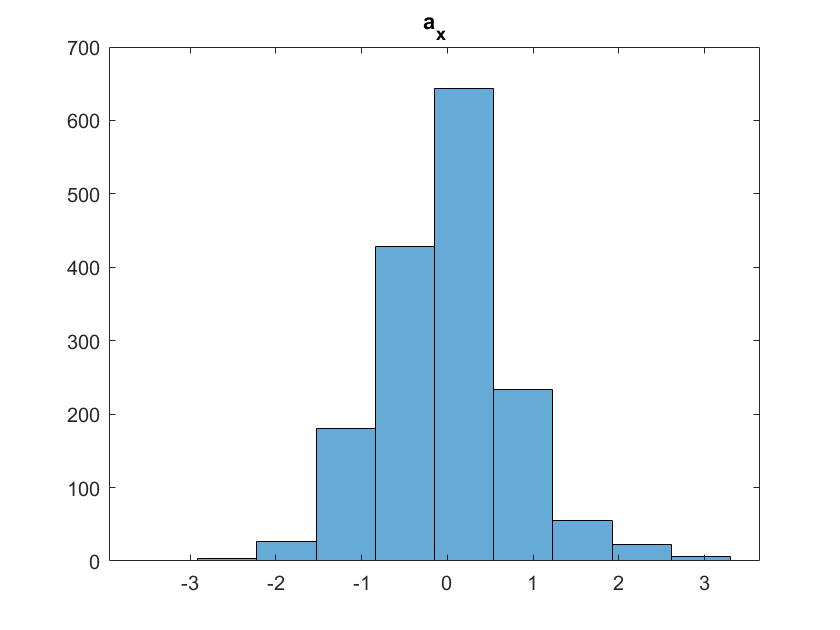

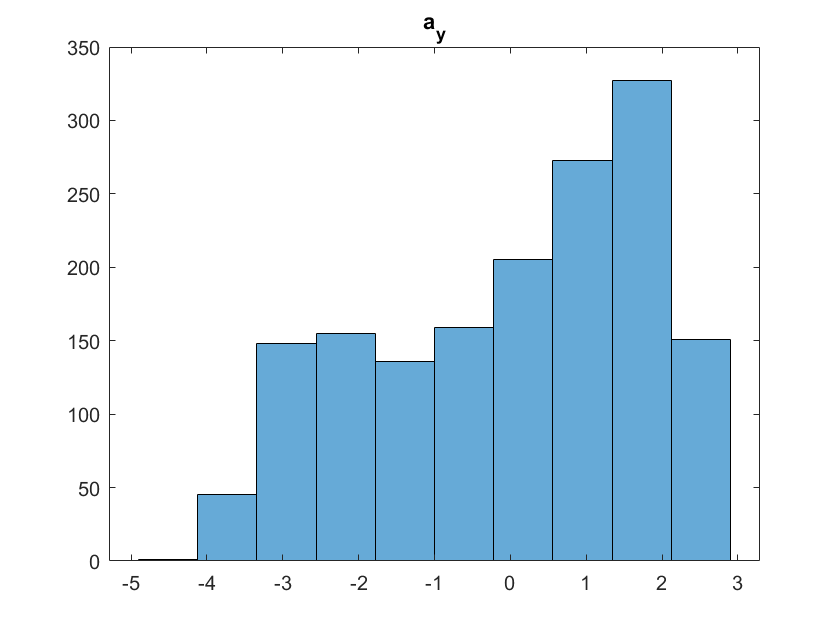

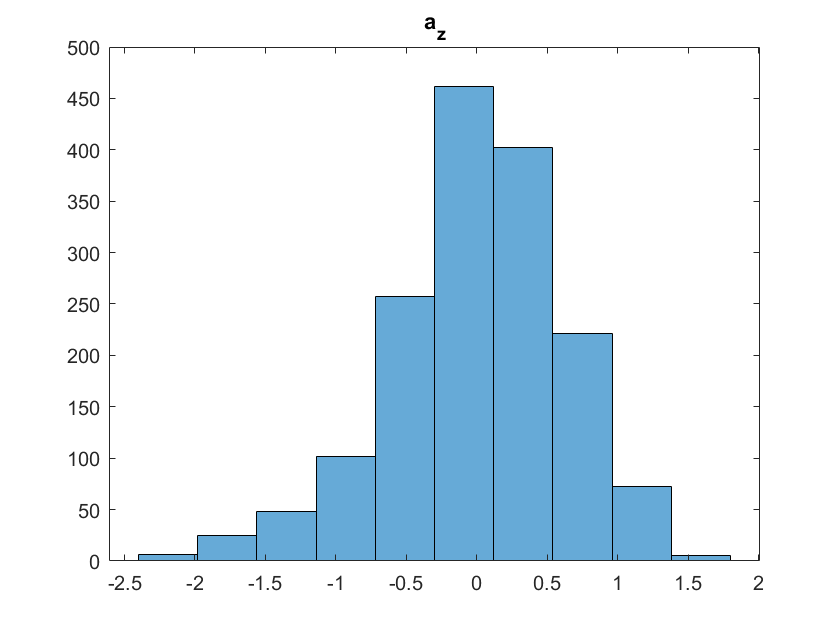

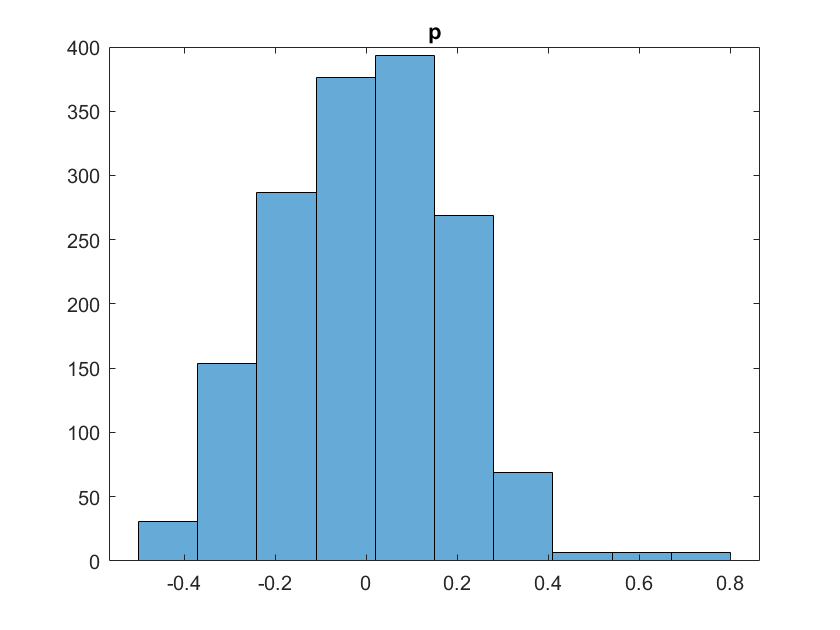

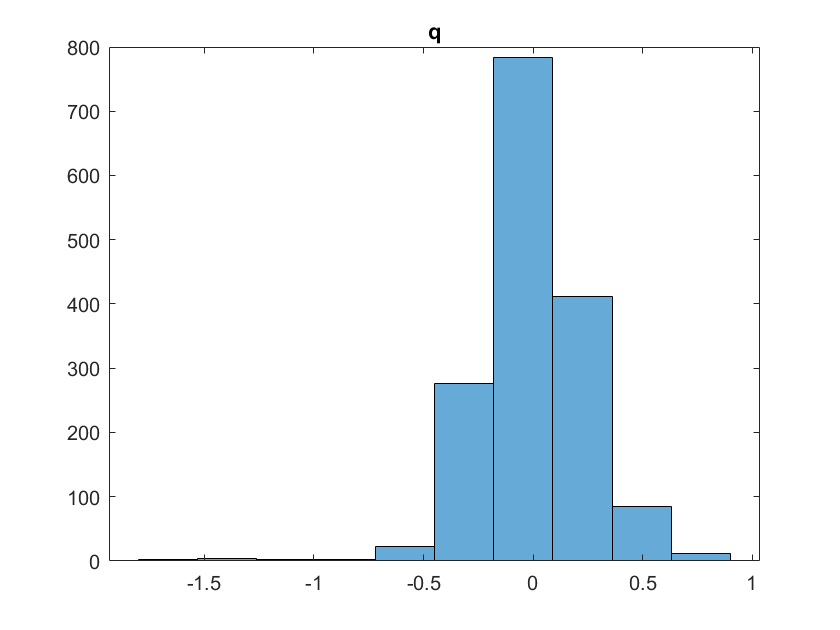

means = zeros(1,size(all_data,2));

for i=1:size(all_data,2)
    means(i) = mean(all_data(:,i));
    noise(:,i) = all_data(:,i) - means(i);
    figure;
    histogram(noise(:,i),10)
    title(labels(i))
end


covariances = cov(noise);

for i=1:size(all_data,2)
    fprintf('Variance of %s is %f \n',labels(i),covariances(i,i));
end

Variance of u is 0.053993 
Variance of v is 0.040670 
Variance of w is 0.854228 
Variance of a_x is 0.603879 
Variance of a_y is 3.186179 
Variance of a_z is 0.383473 
Variance of p is 0.037155 
Variance of q is 0.058542 
Variance of r is 0.038126 
Variance of p_0 is 10.438122 
Variance of z_us is 0.006783 



g = 9.8; % acceleration due to gravity m/s^2
M_air = 0.0289644; % molar mass of air in kg/mol
R = 8.31432; % universal gas constant Nm/mol/k
p0 = 101325 % Pa standard pressure

p0 = 101325

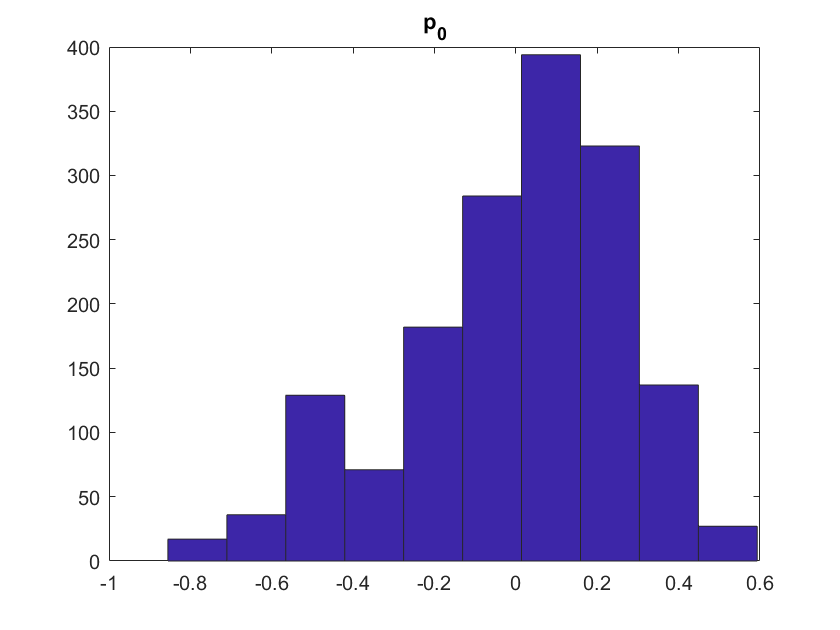

T_kelvin =288.15;  % Assumed temperature in kelvin
K =-g*M_air/R/T_kelvin;
dt = 1/200;
Kappa = 1;


z_hypsometric =@(P) 1/K.*log(P./p0);
p_0_mean = mean(p_0);
difference = z_hypsometric(p_0) - z_hypsometric(p_0_mean);
p_cov = cov(difference); %p_0
hist(difference)
title("p_0")


for i = 1:10
    for j = i:10
        correlation = corr(all_data(:,i),all_data(:,j));
        if abs(correlation) > 0.3 && (i ~= j)
            fprintf('Correlation between %s and %s is %f \n',labels(i),labels(j),corr(all_data(:,i),all_data(:,j)))
        end
    end
end

Correlation between u and a_x is -0.321772 
Correlation between v and p is -0.689924 
Correlation between a_y and a_z is 0.611041 
Correlation between a_y and p_0 is -0.750140 
Correlation between a_z and p_0 is -0.530078 


corr_matrix = corrcoef(all_data);



[A_t_dis,B_t_dis,C_t_dis,D_t_dis] = discretize(A_throttle,[0;1],[1 0],0,dt);
[A_e_dis,B_e_dis,C_e_dis,D_e_dis] = discretize(A_aileron(1:2,1:2),[0;1],eye(2),0,dt); 
[A_a_dis,B_a_dis,C_a_dis,D_a_dis] = discretize(A_elevator(1:2,1:2),[0;1],eye(2),0,dt);

% A_a_dis = expm(A_aileron(1:2,1:2).*dt);
% B_a_dis = A_aileron(1:2,3).*[dt^2/2; dt]; 
% C_a_dis = eye(2);

q_cov = covariances(8,8);
p_cov = covariances(7,7);
% Q_e_dis = q_cov*dt*eye(2);
% Q_a_dis = p_cov*dt*eye(2);
Q_e_dis = B_e_dis*B_e_dis';
Q_a_dis = B_a_dis*B_a_dis';

theta_estimate = atan(-a_x./sqrt(a_y.^2 + a_z.^2));
phi_estimate = atan(a_y./a_z);
v_estimate = 1*z_us.*v;

%R_e = cov([u theta_estimate])
%R_a = cov([v phi_estimate])
R_e = [var(u) 0; 0 var(theta_estimate)];
R_a = [var(v_estimate) 0; 0 var(phi_estimate)];


% A_t_dis = expm(A_throttle.*dt);
% B_t_dis = [dt^2/2; dt];
% C_t_dis = [1 0];

a_z_cov = covariances(6,6);
z_us_cov = covariances(11,11);
r_cov = covariances(9,9);

Q_t_dis = B_t_dis*B_t_dis';
R_t = z_us_cov;


%[test1,test2,test3,test4] = discretize(A_throttle,[0;1],[1 0],0,dt)


function [A_dis,B_dis,C_dis,D_dis] = discretize(A,B,C,D,dt)
C_dis = C;
D_dis = D;
A_dis = expm(A.*dt);
B - sym(B);
syms tao
B_dis = double(int(expm(A*tao),tao,0,dt)*B);

end









